## 基本

潮位推算の地点名・年・月を入力してインスタンスを生成します．

station = JMAtide('能登', 2024, 1)

station =   JMAtide のプロパティ:

              Station: '能登'
                 Year: 2024
                Month: 1
                 Time: []
                Ndays: []
                  SSH: []
           SSHanomaly: []
     AstronomicalTide: []
                  Lon: 137.1500
                  Lat: 37.5000
              URL_ssh: 'https://www.data.jma.go.jp/gmd/kaiyou/data/db/tide/genbo/2024/202401/hry202401SZ.txt'
             URL_ssha: 'https://www.data.jma.go.jp/gmd/kaiyou/data/db/tide/genbo/2024/202401/dep202401SZ.txt'
            URL_astro: 'https://www.data.jma.go.jp/kaiyou/data/db/tide/suisan/txt/2024/SZ.txt'
    RefLevelObs_TP_cm: -121.8000
    RefLevelAst_TP_cm: 5.6000
                 Unit: 'cm'
         StandardTime: 'JST(UTC+9)'
       ReferenceLevel: 'T.P.'


loadastronimocaltide メソッドでそれぞれ潮位，潮位偏差を気象庁ウェブサイトから取得します．

格納されるプロパティ名は AstronomicalTide です．

station = station.loadastronimocaltide; % 推算潮位

plotastronomicaltide で取得したデータの簡易的なプロットが可能です．

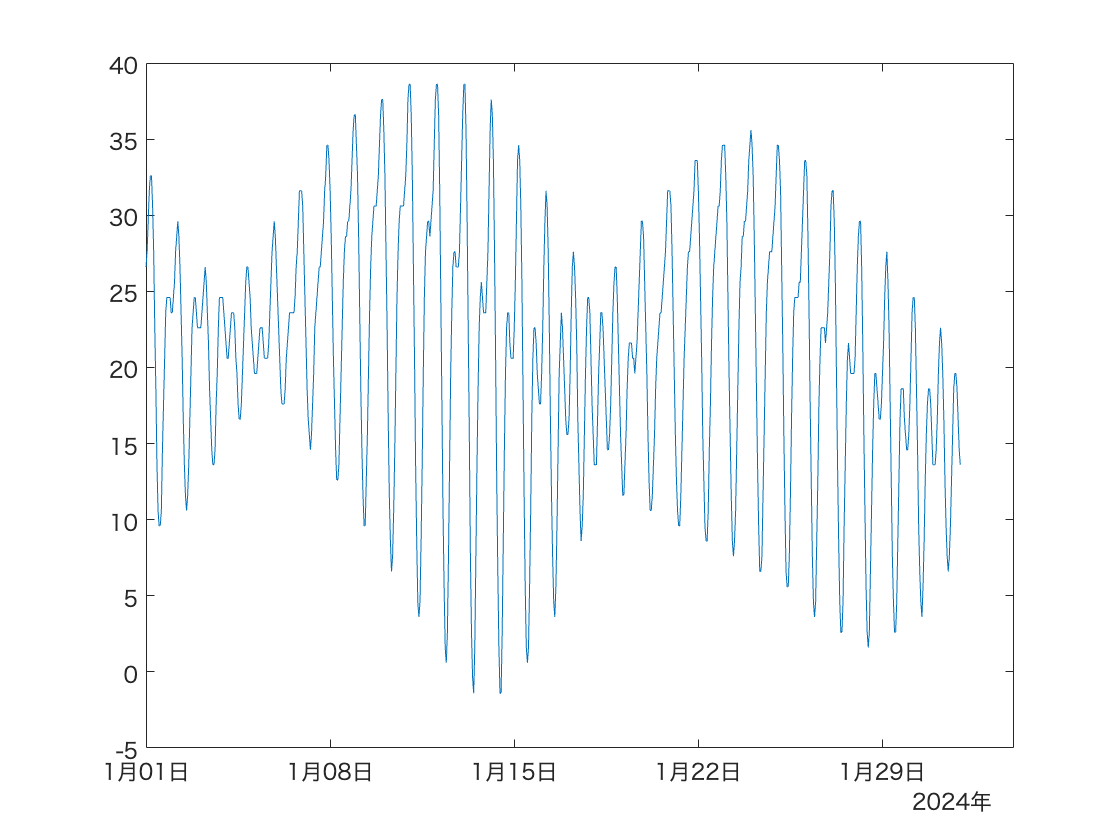

% 潮位のプロット
station.plotastronomicaltide;

## 最も近い潮位表掲載地点の検出

緯度経度を入力して，一番近い潮位表の掲載地点を求めることもできます．

stationname = JMAtide.findNearestStationForAstro([136.674; 137.263], [37.168; 37.434]) % lon, lat

stationname = 2×1 の cell 配列
    {'輪島'}
    {'能登'}


## 特定時刻の推算潮位取得

月ごとの推算潮位を取得後に datetime 型で日時を指定することで，特定時刻の推算潮位を毎時データから内挿で求めることができます．

% 2024年1月
station = JMAtide(stationname, 2024, 1);
% 毎時推算潮位取得
station = station.loadastronimocaltide;
% 特定時刻の推算潮位の抽出 2024/01/25T19:15
atide = station.getastronomicaltide(datetime(2024,1,25,19,15,0,0))

atide =    21.0000
   24.8500


対象期間外の時刻を指定して潮位を取得しようとした場合，NaN を返します．

% 2024年1月でない時刻の指定
station.getastronomicaltide(datetime(2024,2,1,3,10,0,0))

ans =    NaN
   NaN
